


%% gmrt_wind_full.m
% Full GMRT wind force & torque simulation using Davenport (or fallback) filter
% Author: ChatGPT
clear; close all; clc

% -----------------------
% USER INPUTS
% -----------------------
D       = 45;            % dish diameter (m)
R       = D/2;           % radius (m)
rho     = 1.15;          % air density (kg/m^3) - Khodad approx
Cd      = 0.60;          % mesh drag coefficient (dimensionless)
vn      = 3.15;          % mean wind speed (m/s)
z       = 23.16;         % antenna height (m)
z0      = 0.03;         % terrain roughness (m)
rcp_fac = 0.4;           % r_cp factor (fraction of radius)
rcp     = rcp_fac * R;   % effective moment arm (m)

use_user_filter = true;  % true: try to use provided Davenport filter coefficients
rng_seed = 1;            % random seed for reproducibility (set [] to disable)

% Provided discrete "Davenport" coefficients (user-supplied)
b_user = [0.413 0.1762 -1.402 0.1762 0.413];    % numerator (b)
a_user = [1 19.38 -40.79 19.38 1];              % denominator (a)

% -----------------------
% DERIVED / PHYSICAL QUANTITIES
% -----------------------
A  = pi * D^2 / 4;                      % projected area (m^2)
kF = 0.5 * rho * Cd * A;                % steady force coefficient (N/(m/s)^2)

kappa = 1 / ( (2.5 * log(z / z0))^2 );
alpha = sqrt(6 * kappa);

Fm = kF * vn^2;                         % steady (mean) force (N)
kf = 2 * kF * alpha * vn^2;             % gust-force gain (N)  (RMS of gust force when delta_v0 is unit std)

Tm = Fm * rcp;                          % steady torque (N*m)
% Tw_RMS = kf * rcp;                    % gust torque RMS (N*m)  % printed later

% Print summary
fprintf('\n--- GMRT Mesh Dish Wind Load ---\n');


--- GMRT Mesh Dish Wind Load ---


fprintf('Diameter D = %.2f m, Radius R = %.2f m\n', D, R);

Diameter D = 45.00 m, Radius R = 22.50 m


fprintf('Projected area A = %.2f m^2\n', A);

Projected area A = 1590.43 m^2


fprintf('k_F (steady coeff) = %.2f N/(m/s)^2\n', kF);

k_F (steady coeff) = 548.70 N/(m/s)^2


fprintf('F_m (steady force)   = %.2f N (%.2f kN)\n', Fm, Fm/1e3);

F_m (steady force)   = 5444.46 N (5.44 kN)


fprintf('k_f (gust gain RMS)  = %.2f N (%.2f kN)\n', kf, kf/1e3);

k_f (gust gain RMS)  = 1604.59 N (1.60 kN)


fprintf('T_m (steady torque)  = %.2f N*m (%.2f kN*m)\n\n', Tm, Tm/1e3);

T_m (steady torque)  = 49000.17 N*m (49.00 kN*m)




% -----------------------
% SIMULATION / TIME SETTINGS
% -----------------------
Ts   = 0.02;     % sampling time (s)
Tdur = 200;      % duration (s)
N    = round(Tdur / Ts);
t    = (0:N-1)' * Ts;

% seed RNG if requested
if ~isempty(rng_seed)
    rng(rng_seed);
end

% -----------------------
% CREATE SHAPED UNIT-STANDARD GUST SERIES delta_v0(t)
% Try user filter if requested & stable, else fallback to Butterworth shaping
% -----------------------
wn = randn(N,1);    % white noise, unit variance

use_fallback = false;
if use_user_filter
    % Check stability of user filter
    poles = roots(a_user);
    if all(abs(poles) < 1)
        % stable: use zero-phase filtering to avoid phase distortion
        try
            delta_v0 = filtfilt(b_user, a_user, wn);
            method_used = 'user discrete filter (filtfilt)';
            % sanity check on output
            if ~isfinite(std(delta_v0)) || std(delta_v0) == 0
                warning('User filter produced invalid output; switching to fallback shaping.');
                use_fallback = true;
            end
        catch ME
            warning('Error applying user filter: %s\nSwitching to fallback shaping.');
            use_fallback = true;
        end
    else
        warning('User filter is unstable (poles outside unit circle). Using fallback shaping.');
        use_fallback = true;
    end
else
    use_fallback = true;
end

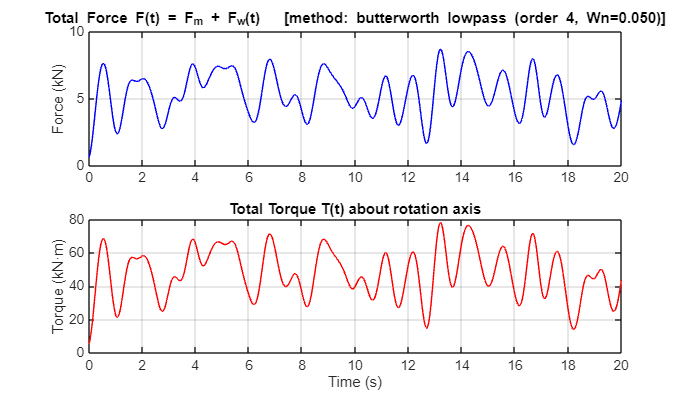


if use_fallback
    % Fallback: 4th-order lowpass Butterworth (normalized cutoff chosen to give low-freq energy)
    ord = 4;
    Wn = 0.05;  % normalized cutoff (0-1, 1 = Nyquist). adjust if needed.
    [b_but,a_but] = butter(ord, Wn);
    delta_v0 = filtfilt(b_but, a_but, wn);
    method_used = sprintf('butterworth lowpass (order %d, Wn=%.3f)', ord, Wn);
end

% Normalize to unit standard deviation safely
sigma = std(delta_v0);
if sigma > 0 && isfinite(sigma)
    delta_v0 = delta_v0 / sigma;
else
    error('Filtered gust signal has zero or invalid standard deviation. Check filter/coefs.');
end

% -----------------------
% COMPUTE FORCE & TORQUE TIME SERIES
% -----------------------
F_w_t = kf * delta_v0;           % gust force component (N)
F_t   = Fm + F_w_t;              % total force (N)
T_t   = F_t * rcp;               % total torque about rotation axis (N*m)

% -----------------------
% PLOTTING
% -----------------------
figure('Name','Gust Force & Torque Time Series','NumberTitle','off','Position',[200 200 900 520]);

subplot(2,1,1);
plot(t, F_t/1e3, 'b'); grid on;
ylabel('Force (kN)');
title(sprintf('Total Force F(t) = F_m + F_w(t)   [method: %s]', method_used));
xlim([0 min(Tdur,20)]);  % show first 20 seconds for clarity; change as desired

subplot(2,1,2);
plot(t, T_t/1e3, 'r'); grid on;
ylabel('Torque (kN·m)');
xlabel('Time (s)');
title('Total Torque T(t) about rotation axis');
xlim([0 min(Tdur,20)]);


% -----------------------
% SUMMARY CHECKS / STATS
% -----------------------
fprintf('Filter method used: %s\n', method_used);

Filter method used: butterworth lowpass (order 4, Wn=0.050)


fprintf('std(F_w) = %.2f N (should be ~= k_f = %.2f N)\n', std(F_w_t), kf);

std(F_w) = 1604.59 N (should be ~= k_f = 1604.59 N)


fprintf('std(T_w) = %.2f N*m (should be ~= k_f * rcp = %.2f N*m)\n\n', std(F_w_t)*rcp, kf*rcp);

std(T_w) = 14441.35 N*m (should be ~= k_f * rcp = 14441.35 N*m)



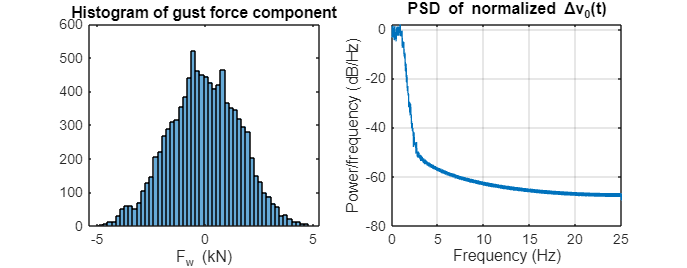


% Optionally show histograms or PSDs
figure('Name','Diagnostics','NumberTitle','off','Position',[300 300 900 350]);
subplot(1,2,1);
histogram(F_w_t/1e3,50); xlabel('F_w (kN)'); title('Histogram of gust force component');
subplot(1,2,2);
pwelch(delta_v0,[],[],[],1/Ts); title('PSD of normalized Δv_0(t)');


% Save data if desired
% save('gmrt_wind_timehistory.mat','t','delta_v0','F_t','F_w_t','T_t','Fm','kf','kF','rcp');

